x = [1,2,3,4,5,6,7,8];
N = [2,5,2,1,1,0,2,1]/14;
[d,a] = huffmandict(x,N);

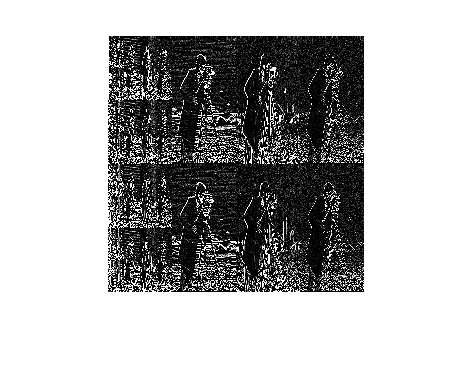

image = imread('Important_files/cameraman.tif');
[c, s] = wavedec2(image, 5, 'Haar');
I_FWT = reshape(c, 256, 256); 
[counts, bin_locations] = imhist(I_FWT);
imshow(I_FWT, [0 10]);


[dict,a_wavelet] = huffmandict(0:255,counts/sum(counts));

dft = fft2(image);
real = abs(dft);
imaginary = angle(dft);

[counts_fori_real, ] = imhist(real);
[counts_fori_imag, ] = imhist(imaginary);

[dict_fori_real,a_fori_real] = huffmandict(0:255,counts_fori_real/sum(counts_fori_real));
[dict_fori_imag,a_fori_imag] = huffmandict(0:255,counts_fori_imag/sum(counts_fori_imag));

a_dft = (a_fori_real + a_fori_imag)/2;

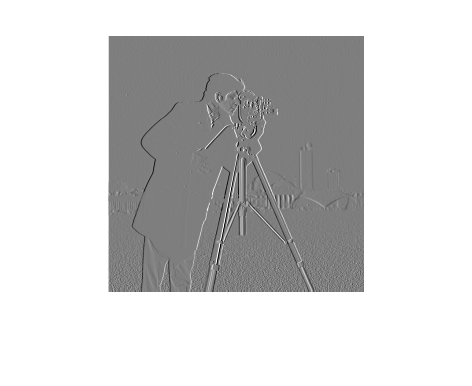

new_image = [zeros(256,1), image(:,1:255)];

error = int16(image) - int16(new_image);

imshow(error, [])


[counts_pred, bin_locations_pred] = imhist(error);
[dict_pred,a_pred] = huffmandict(0:255,counts_pred/sum(counts_pred));

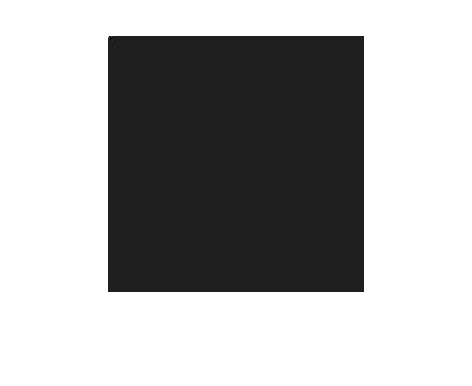

image_dct = dct2(image);

imshow(image_dct, [])


[counts_dct, bin_locations_dct] = imhist(image_dct);
[dict_dct,a_dct] = huffmandict(0:255,counts_dct/sum(counts_dct));